clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
addpath('E:\PhD\meetings_n_conf\2022\wk 14\Colormaps\Colormaps (5)\Colormaps')

S =data_list_adamantane;

## import the data if already converted to ANA

for f = 3%1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata);
    data_converted(f) = macro.convert(data_corrected, mdata);
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv(f) = (S(f).photon);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.54513


## PIPICO

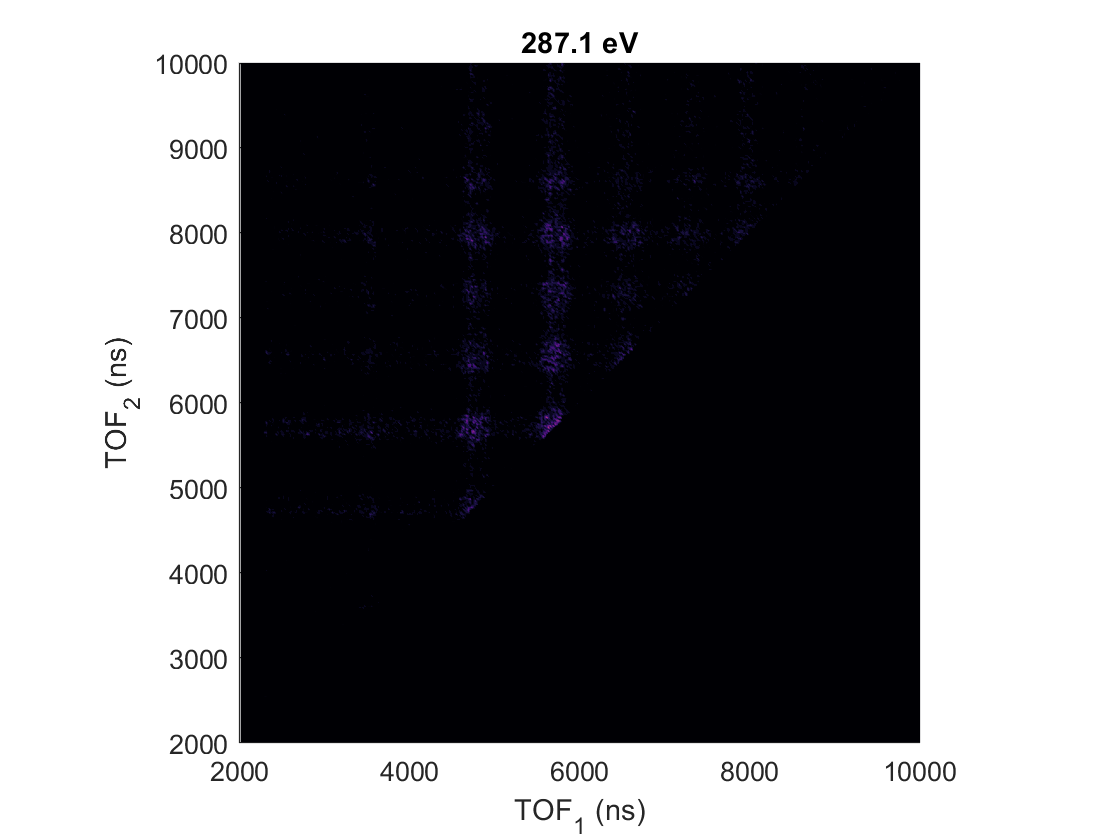

figure; hold on
for i=3;%1:length(S)
%     subplot(1,3,i)
    [Tet_tof2] = plot_pipico(data_converted(i), data_stats(i));
% %     [Tet_tof2] = plot_p_norm_p_norm(data_converted(i), data_stats(i),roi,m2q_1,m2q_2);
    title([num2str(hv(i)), ' eV'])
end
cm_magma=magma(20);
colormap(cm_magma)

 [centres, electron_KE] = get_AES(data_converted(3), data_stats(3))

centres =   200.2500  200.7500  201.2500  201.7500  202.2500  202.7500  203.2500  203.7500  204.2500  204.7500  205.2500  205.7500  206.2500  206.7500  207.2500  207.7500  208.2500  208.7500  209.2500  209.7500  210.2500  210.7500  211.2500  211.7500  212.2500  212.7500  213.2500  213.7500  214.2500  214.7500  215.2500  215.7500  216.2500  216.7500  217.2500  217.7500  218.2500  218.7500  219.2500  219.7500  220.2500  220.7500  221.2500  221.7500  222.2500  222.7500  223.2500  223.7500  224.2500  224.7500


electron_KE = struct with fields:
     ES_0: [1×200 double]
     ES_1: [1×200 double]
     ES_2: [1×200 double]
     ES_3: [1×200 double]
     ES_4: [1×200 double]
      AES: [1×200 double]
    BES_1: [1×200 double]
    BES_2: [1×200 double]
    BES_3: [1×200 double]
      BES: [1×200 double]
    TES_0: [1×200 double]
    TES_1: [1×200 double]
    TES_2: [1×200 double]
    TES_3: [1×200 double]
      TES: [1×200 double]


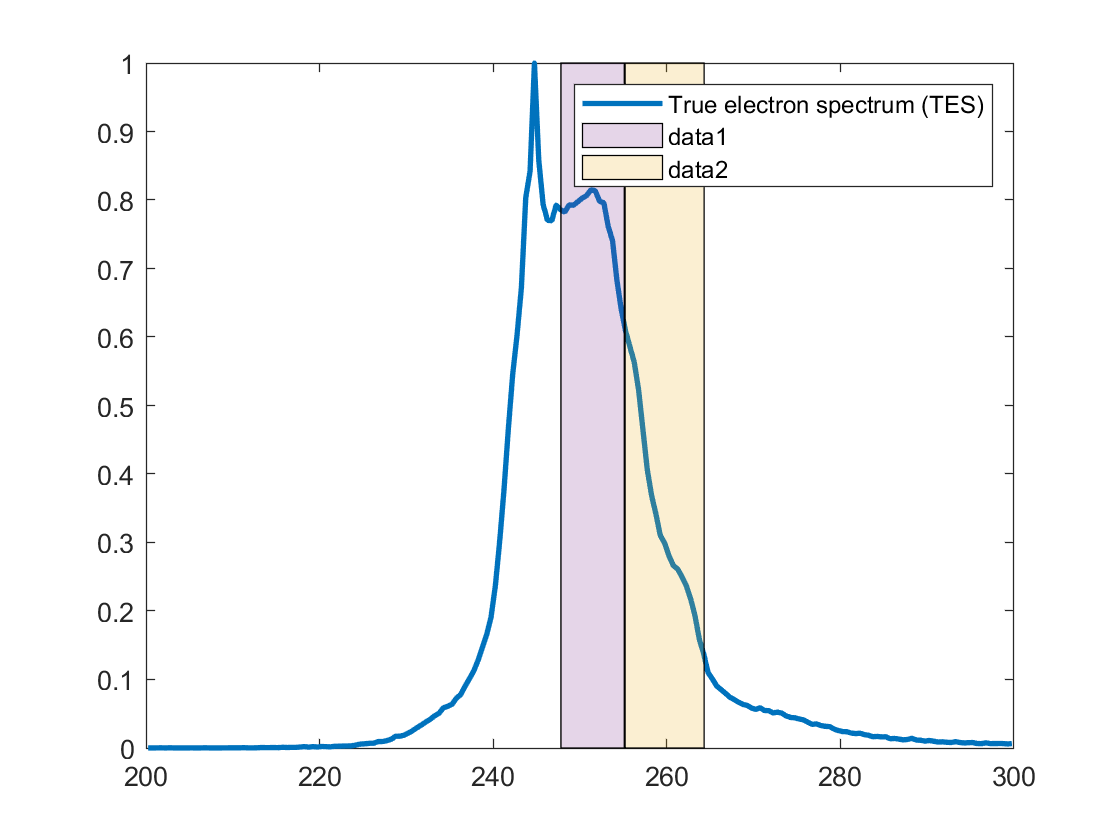

 es_range1 = [247.8;255.1]; %cH2 
es_range2 = [255.2;264.3]; %CH
yl= ylim;
patch([es_range1(1),es_range1(1),es_range1(2),es_range1(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.4940 0.1840 0.5560])
patch([es_range2(1),es_range2(1),es_range2(2),es_range2(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.9290 0.6940 0.1250])

## PIPICO (ES FILTERED)

f1 =figure; hold on
% es_range = [230;280]; %all
ch = subplot(1,2,1);
es_range = [255.2;264.3]; %CH
% es_range = [255.2;260.7]; %CH
for i=3
% %     subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2,Bincenters] = plot_pipico_es_filt(data_converted(i),mdata,  data_stats_es_filt(i),es_range);
%     title([num2str(hv(i)), ' eV'])
end

The Scaling factor is 0.099211


cm_magma=magma(20);
colormap(cm_magma)

% f1;
ch2 = subplot(1,2,2);
es_range = [247.8;255.1]; %cH2
% es_range = [250.25;254.5]; %cH2
for i=3
% %     subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2,Bincenters] = plot_pipico_es_filt(data_converted(i), mdata, data_stats_es_filt(i),es_range);
%     title([num2str(hv(i)), ' eV'])
end

The Scaling factor is 0.18151


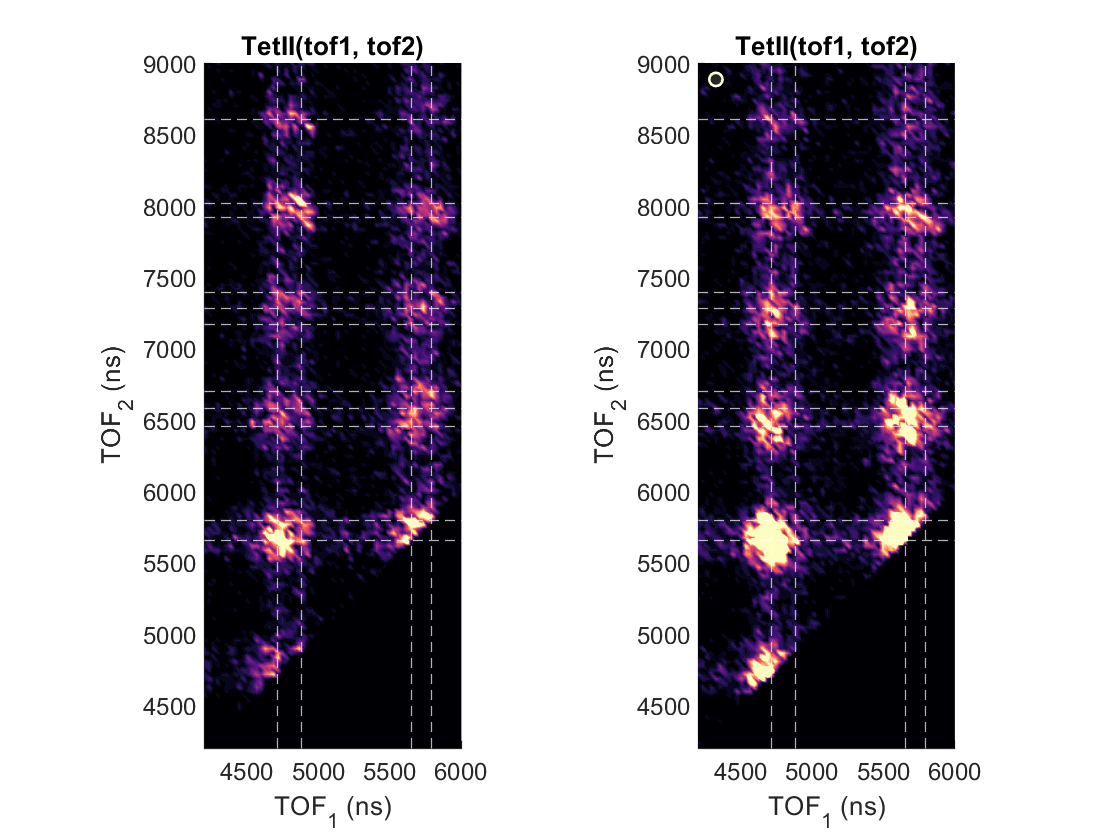

colormap(cm_magma)

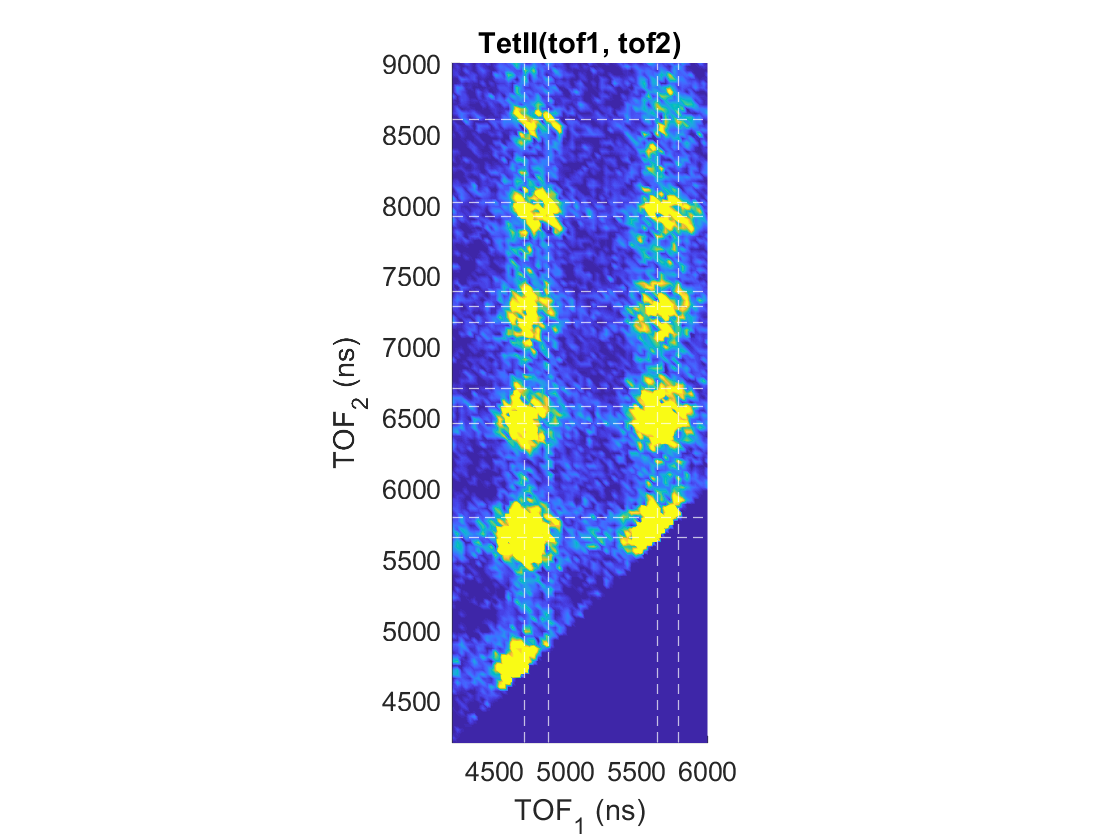

The Scaling factor is 0.50242


f1 =figure; hold on
es_range = [230;280]; %all
% ch = subplot(1,2,1);
% es_range = [255.2;264.3]; %CH
% es_range = [255.2;260.7]; %CH
for i=3
% %     subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2,Bincenters] = plot_pipico_es_filt(data_converted(i),mdata,  data_stats_es_filt(i),es_range);
%     title([num2str(hv(i)), ' eV'])
end

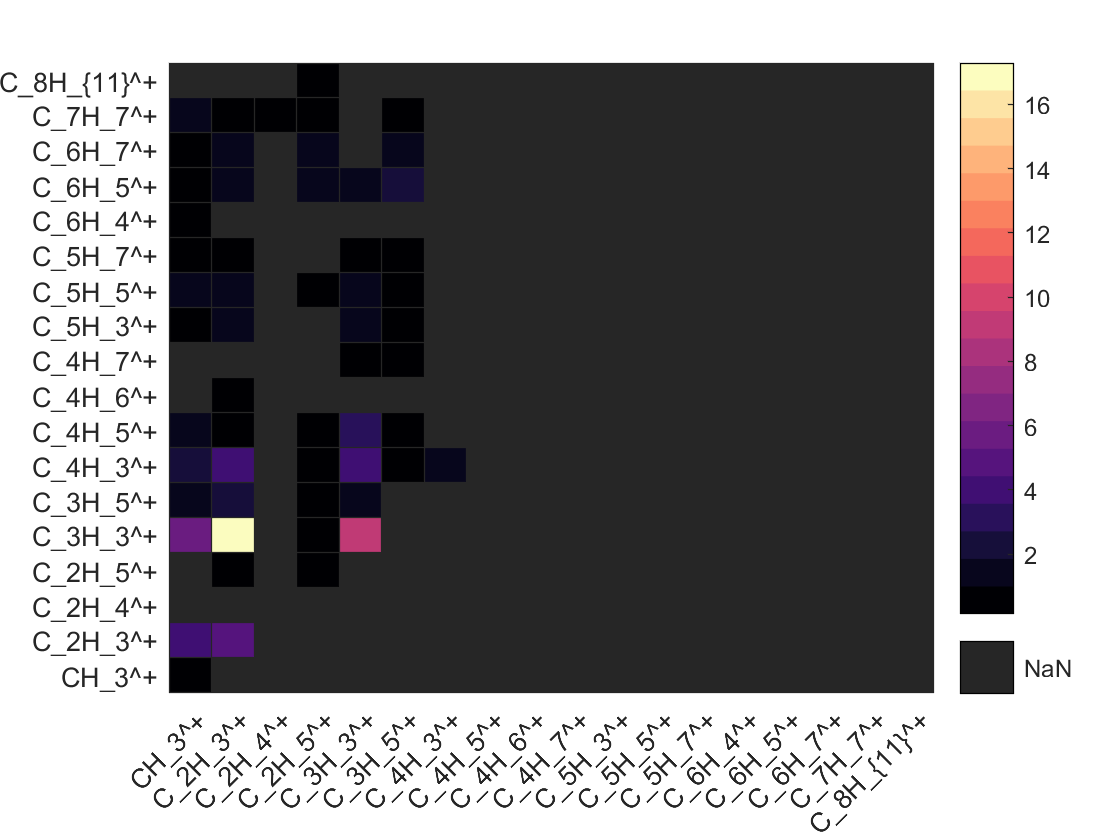


% sgtitle(sprintf('Region 0 : %.0f eV - %.1f eV', es_range(1),es_range(2)))
roi_path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';
[xvalues, d] = get_counts_in_roi(roi_path, Tet_tof2, Bincenters );
c =d;
% c = NaN(length(xvalues),length(xvalues));
% c(:,2:4) =d(:,2:4);
yvalues =xvalues;
counts= sum(c,'all','omitnan');
cdata = c.*100./counts;
figure
h = heatmap(xvalues,flip(yvalues),flip(cdata));
cm_magma=magma(20);
colormap(cm_magma)

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
The number of events in ROI are 561


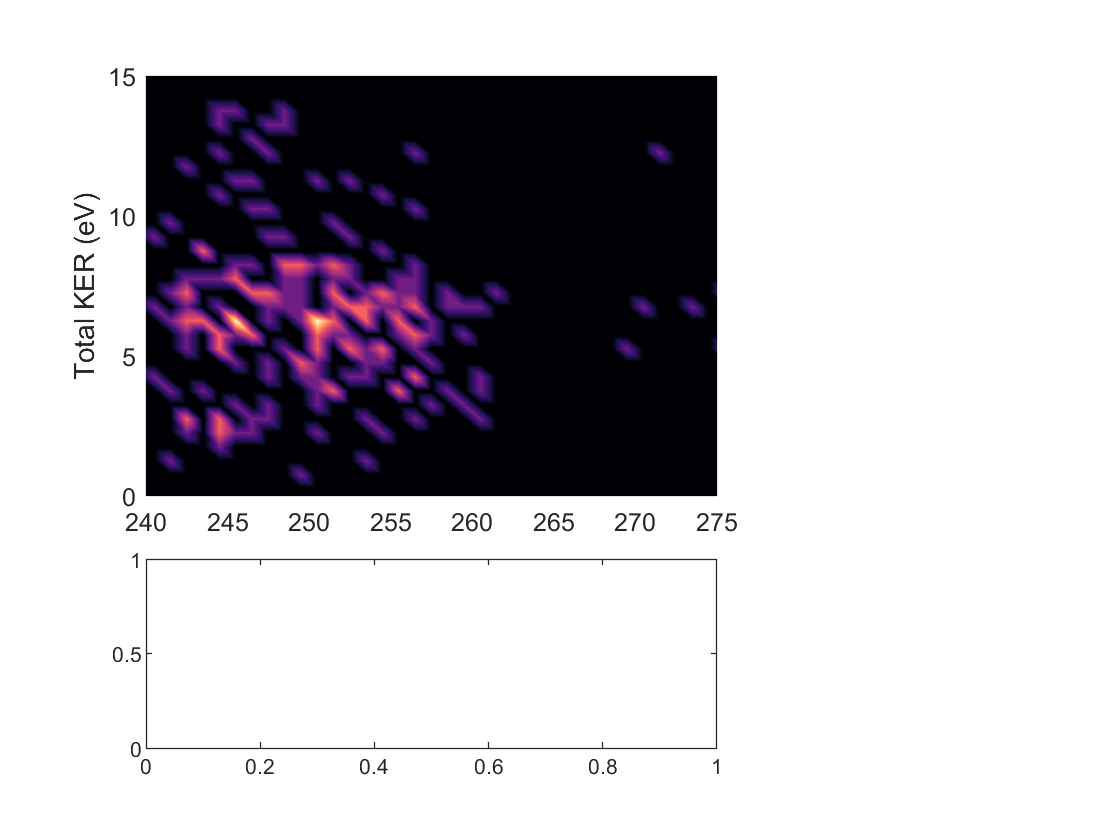

The Scaling factor is 0.51938


roi_path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';
plot_AES_KER(roi_path,data_corrected)


 [xvalues, c, d] = get_ker_in_roi(roi_path,data_corrected)
 yvalues =xvalues;
 %%


figure
h = heatmap(xvalues,flip(yvalues),flip(c));
cm_magma=magma(20);
colormap(cm_magma)
h.CellLabelFormat ='%0.2f ±  ';

figure
h = heatmap(xvalues,flip(yvalues),flip(d));
cm_magma=magma(20);
colormap(cm_magma)


A = imread('E:\PhD\meetings_n_conf\2022\wk 16\ION_KER_ALL.png');
image(A)
e= flip(d);
    xx= 170;
for hh=1:length(d)
        yy= 430;
   for kk= 1:length(d)
       if ~isnan(e(hh,kk))
            text(yy,xx,sprintf('%0.2f',e(hh,kk)),'Color','w','FontSize',8)
       end
       yy = yy+230;
   end
   xx=xx+75;
end

% figure
% counts= sum([c{:,2}])./100;
% cdata =NaN(8,8);
% cdata(1:7,1)=[c{1:7,2}]./counts;
% cdata(2:8,2)= [c{8:14,2}]./counts;
% cdata(3:7,3)= [c{15:19,2}]./counts;
% cdata(4:6,4)= [c{20:22,2}]./counts;
% cdata(5,5)= [c{23,2}]./counts;
% labels =cell(1,8); for n=1:8; labels{1,n} = sprintf('C%i',n); end
% xvalues = labels; yvalues = labels;
% h = heatmap(xvalues,flip(yvalues),flip(cdata));
% colormap('hot')

%%

roi_path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';
[xvalues, c, d]  = get_ES_ion_pair_roi(roi_path,data_converted(3), data_stats(3))
yvalues =xvalues;
 %%


figure
h = heatmap(xvalues,flip(yvalues),flip(c));
cm_magma=magma(20);
colormap(cm_magma)
h.CellLabelFormat ='%0.2f ±  ';

figure
h = heatmap(xvalues,flip(yvalues),flip(d));
cm_magma=magma(20);
colormap(cm_magma)


A = imread('E:\PhD\meetings_n_conf\2022\wk 16\ION_AES_ALL.png');
figure
image(A)
e= flip(d);
    xx= 170;
for hh=1:length(d)
        yy= 418;
   for kk= 1:length(d)
       if ~isnan(e(hh,kk))
            text(yy,xx,sprintf('%0.2f',e(hh,kk)),'Color','w','FontSize',7)
       end
       yy = yy+210;
   end
   xx=xx+75;
end

## Load ROI

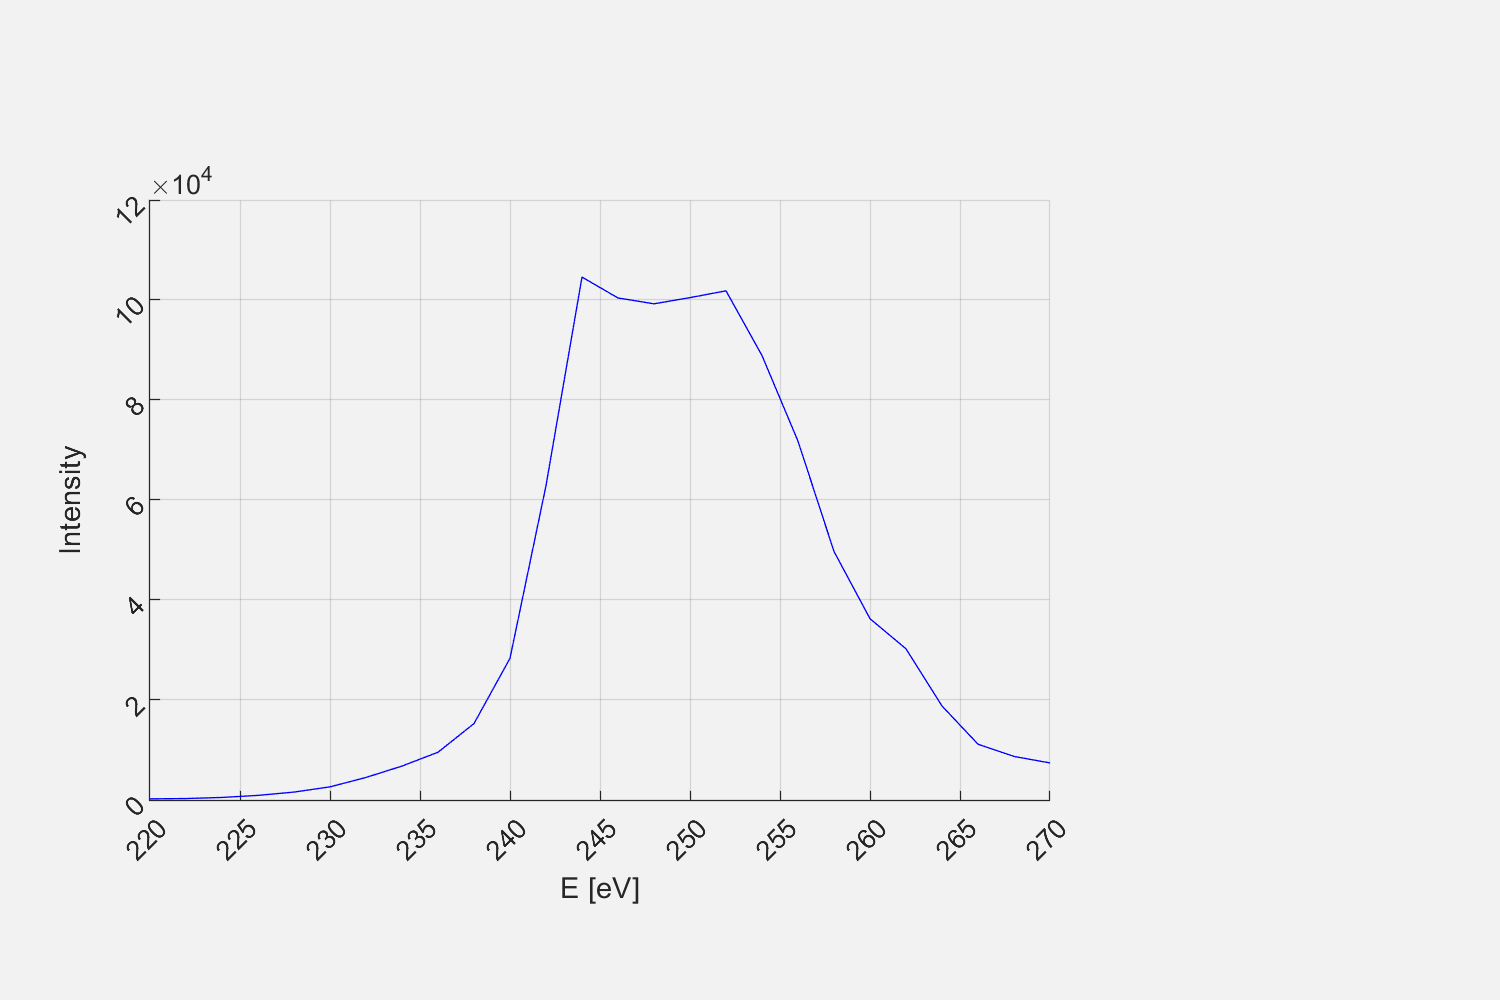

c1 = 2;  h1 =3; c2= 3; h2=3;
m2q_1 = 12*c1+h1; m2q_2 = 12*c2+h2;
filename= sprintf('c%ih%i_c%ih%i',c1,h1,c2,h2);
% filename= sprintf('c%i_c%i',c1,c2);

roi_path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final\';%_carbons_new\new_folder';
load([roi_path,filename,'.mat'],'roi')
mdata = IO.import_metadata(S(3).dir_ada);
mdata.plot.det2.TOF_hit1_hit2.cond.C2H5.value=m2q_1;
mdata.plot.det2.TOF_hit1_hit2.cond.C8H11.value=m2q_2;
macro.plot(data_converted(3),mdata);

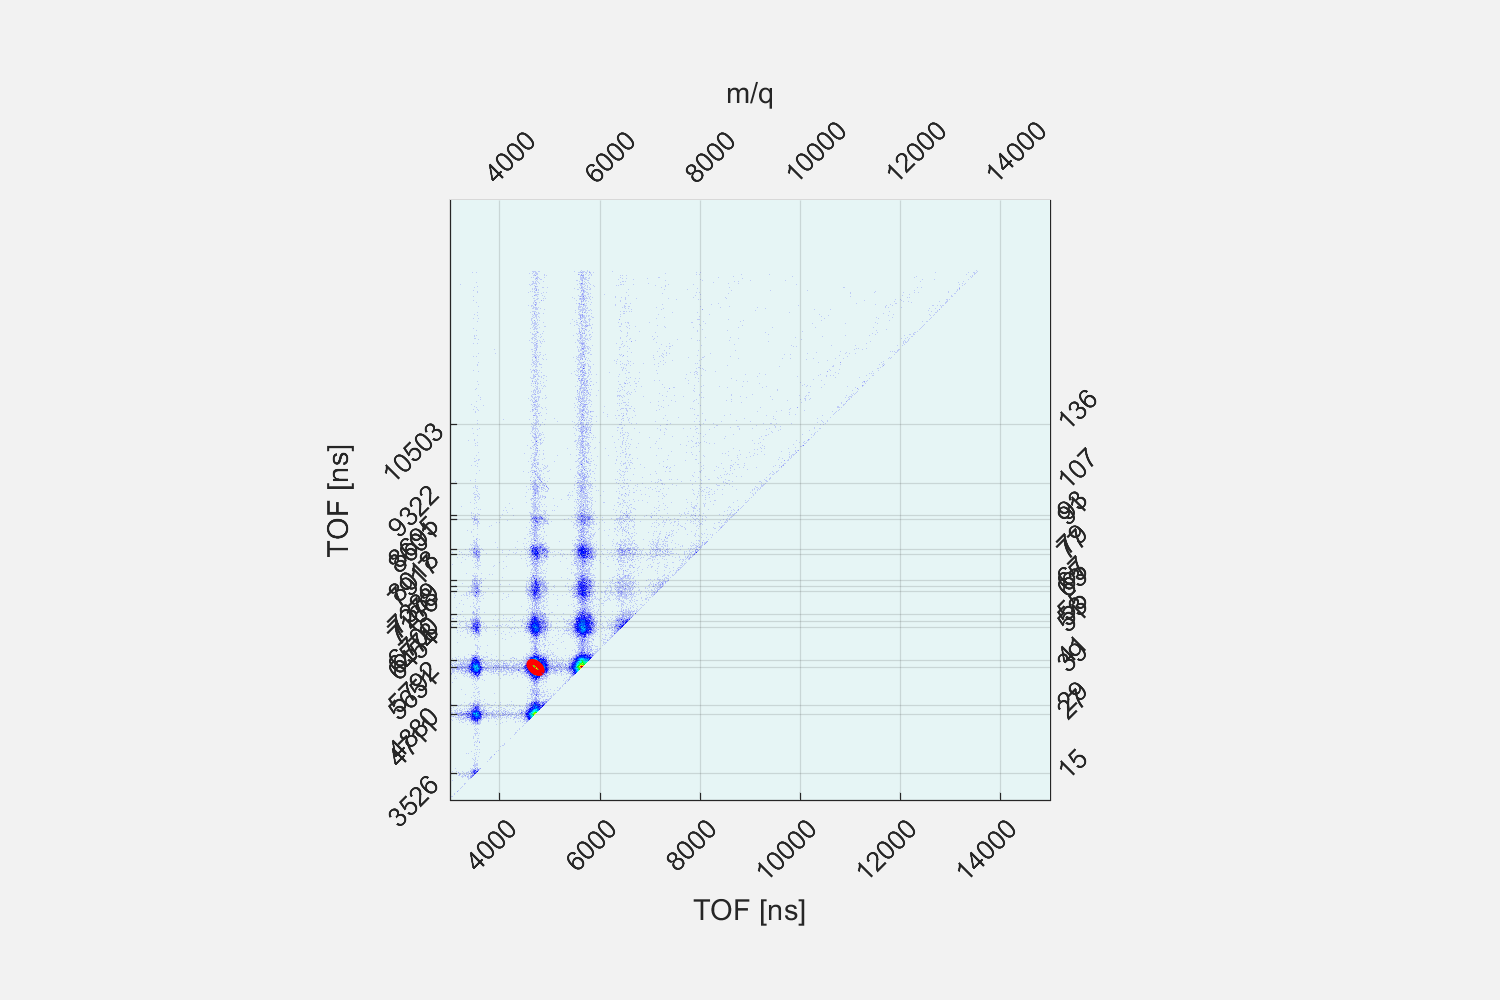

drawellipse('Color','r', 'Center',roi.Center,'SemiAxes',roi.SemiAxes,'FaceAlpha',0,'InteractionsAllowed','none','RotationAngle',roi.RotationAngle);

## ION Kinetic energy Two ion events

% [e_filter_roi, ~] = filter.epicea.find_events_in_roi(data_converted(3),roi,m2q_1,m2q_2);
[e_filter_roi, ~] = find_events_in_roi(data_converted(3),roi);

The number of events in ROI are 13983


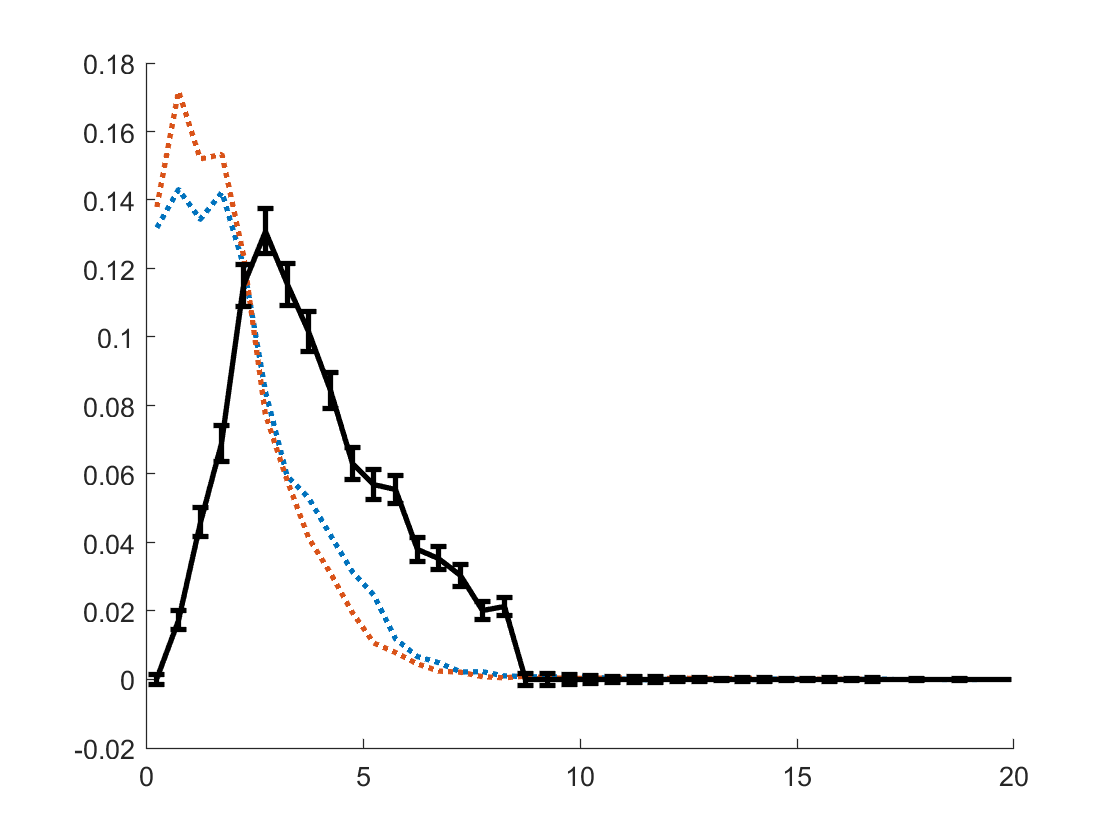


figure; hold on
plot_signal=struct();
plot_signal.hit.data_pointer = 'data_converted.h.det2.KER';
% plot_signal.hit.data_pointer = 'data_converted.h.det2.R';
plot_signal.hit.label = 'Ion kinetic energy (eV)';%dp_{norm}
% plot_signal.Binsize =2; plot_signal.Range =[0, 30]; 
plot_signal.Binsize =0.5; plot_signal.Range =[0, 20]; 
% plot_signal.Binsize =0.1; plot_signal.Range =[0, pi]; 

plot_signal.event.data_pointer = 'data_converted.e.det2.KER_sum';
% plot_signal.event.data_pointer = 'data_converted.e.det2.angle_p_corr_C2';
plot_signal.event.label = 'Ion pair KER (eV)';%p_{1z} + p_{2z}
[Tet_ev_mean,Tet_ev_std] =plot.epicea.plot_ion_c2(data_converted(3), data_stats(3),e_filter_roi,plot_signal,m2q_1,m2q_2);

% legend(filename)

% figure; hold on
% plot_signal=struct();
% plot_signal.hit.data_pointer = 'data_converted.h.det2.dp_norm';
% plot_signal.hit.label = 'Ion |p|';%dp_{norm}
% plot_signal.Binsize =10; plot_signal.Range =[0, 300]; 
% 
% plot_signal.event.data_pointer = 'data_converted.e.det2.dp_sum_norm';
% plot_signal.event.label = 'Ion pair |p_{1} + p_{2}|';%p_{1z} + p_{2z}
% [e_filter_et,e_filter_rt] =plot.epicea.plot_ion_c2(data_converted(3), data_stats(3),e_filter_roi,plot_signal,m2q_1,m2q_2);
% legend(filename)

## Ion pair specific Electron Spectra

% macro.plot(data_converted, mdata)
figure
tof_1 =[roi.Center(1)-500 ; roi.Center(1)+500];
tof_2 =[roi.Center(2)-500 ; roi.Center(2)+500];
[TES2IIpair_x, Xcenters] = plot_ES_ion_pair_c2(data_converted(3), data_stats(3),roi,tof_1,tof_2,0);
%% give name
e_KE_mean = sum(TES2IIpair_x.*Xcenters)/sum(TES2IIpair_x)

